# Analysis

## Import saved dataset

clearvars;
% eeglab; close;
trials = {'001-AOE', '002-AO', '003-AOE'};

filepath = 'C:\\Users\\anhtn\\OneDrive - PennO365\\Documents\\GitHub\\analysis\\Datasets\\';

ALLEEG = cell(1,3);
for i=1:length(trials)
    filename = [trials{i} '-preprocessed.set']; % manually type to select dataset
    ALLEEG{i} = pop_loadset('filename', filename, 'filepath', filepath);
end

pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\001-AOE-preprocessed.set ...
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\002-AO-preprocessed.set ...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\003-AOE-preprocessed.set ...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...



trial_N = 2;
EEG = ALLEEG{trial_N};
plot_folder = ['plot-' trials(trial_N) '\\' ];

###  Parameters

chan_names = {'C3', 'C4'};
RH_cluster = {'C4', 'FC2', 'FC6', 'F4'};
LH_cluster = {'C3', 'FC5', 'FC1', 'F3'};
all_elec = [RH_cluster LH_cluster];
elec_plot = {all_elec}; % plot PSD of EEG at all relevant electrodes

theta_band = {4:8};
alpha_l_band = {8:10};
alpha_h_band = {10:13};
alpha_band = {8:13};
beta_band = {13:30};
freq_bands = [theta_band, alpha_band, beta_band];
band_names = ["theta" "alpha" "beta"];
band_colors = ['b','r','g'];
freq_bands_bl = [theta_band,  alpha_band, beta_band];

freqs_array = [4,8,10,13,30];

markerVal_string = ["10" "11" "12" "13" "14" "15" "16" "17"...
    "20" "21" "22" "23" "24" "25" "26" "27" ...
    "30" "31" "32" "33" "34" "35" "36" "37" ...
    "40" "41" "42" "43" "44" "45" "46" "47"];
markerVal_num = [10  11  12  13  14  15  16  17 20  21  22  23  24  25  26  27  30  31  32  33  34  35  36  37  40  41  42  43  44  45  46  47];
markerVal_AE_num = markerVal_num + 100;
markerLabel = ["human-left", "human-right", "robot-left", "robot-right"];
actor_pair = {[1 2], [3 4]};
side_pair = {[1 3], [2 4]};
actor_pair_names = cell(1,2);
for i = 1:2
        actor_pair_names{i} = [markerLabel(actor_pair{i})];
end
side_pair_names = cell(1,2);
for i = 1:2
        side_pair_names{i} = [markerLabel(side_pair{i})];
end
actions_type1 = [3 4 5 6]; % first sec still hand
actions_type2 = [0 1 2 7]; % first sec moving hand (pre-action)
actions = {actions_type1, actions_type2};
actions_type_names = {'1st-sec still hand', '1st-sec pre-action'};
freqfac = 2;
timesout_stim = 400;

    EEG = ALLEEG{trial_N};

    base_tlen = [0 8];
    [spectra_base, ~, ~] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3'}}, freqfac, "", [], 'off');

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.




    corrcoef_cell = [];
    for t = base_tlen(1)+1:base_tlen(2)
        tlen = t-1:t;
        EEG_cond_epoch = cond_epoch(EEG, {'1000'}, tlen);
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
        [spectra,freqs,~,~,~] = pop_spectopo(EEG_cond_chan, 1, [tlen(1) tlen(end)]*1000, 'EEG',...
            'freq', freqs_array, 'plot', 'off', 'verbose', 'off', 'freqfac', freqfac);
        R = 0;
        for f = 1:length(freq_bands_bl)
            spectra_band = spectra(1, freqs >= freq_bands_bl{f}(1) & freqs <= freq_bands_bl{f}(end));
            spectra_base_band = spectra_base( freqs >= freq_bands_bl{f}(1) & freqs <= freq_bands_bl{f}(end));
            R_band = corrcoef(spectra_band, spectra_base_band);
            R = R + R_band(1,2);
        end
        R = R/3;
        corrcoef_cell = [corrcoef_cell R];
    end

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


    corrcoef_cell

corrcoef_cell =     0.7405    0.7659    0.5040    0.9447    0.8082    0.8254    0.7671    0.8343


    [~, idx_base] = max(corrcoef_cell)

idx_base = 4

## Baseline epochs and compute PSD of baseline

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
..
Plotting scalp distributions: .....
Click on each trace for channel/component index


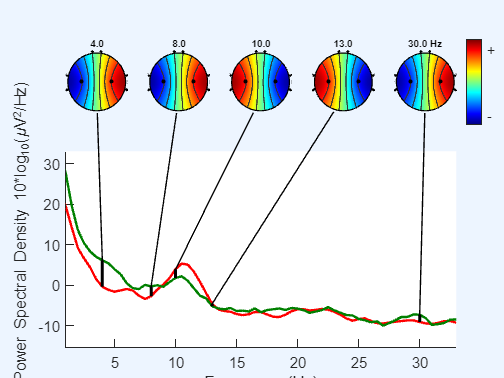

base_tlen = [0 8];
cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3', 'C4'}},freqfac, "", [], 'on');

% 
% EEG_cond_epoch = pop_epoch(EEG, {'1000'}, base_tlen);
% EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
% figure(); title('baseline')
% pop_newtimef(EEG_cond_chan, 1, 1, base_tlen*1000, [3 15.36], ...
%     'freqs', [4 30],'nfreqs', length(4:0.5:30), 'plotitc', 'off', 'plotersp', 'on', ...
%     'verbose', 'off', 'baseline', NaN);
% 
% stim_tlen = [-0.5 4];
% i=1;
% EEG_cond_epoch = pop_epoch(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen);
% EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
% figure(); title('stim')
%     pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 15.36], ...
%     'freqs', [4 30],'nfreqs', length(4:0.5:30), 'plotitc', 'off', 'plotersp', 'on', ...
%     'verbose', 'off', 'baseline', NaN);

## Check correlation: comparing power spectrum of 1-sec window with that of full-length baseline epochs (C3)

base_tlen = [0 8];
[spectra_base, ~, ~] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3'}}, freqfac, "", [], 'off');

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.




corrcoef_cell = [];
for t = base_tlen(1)+1:base_tlen(2)
    tlen = t-1:t;
    EEG_cond_epoch = cond_epoch(EEG, {'1000'}, tlen);
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
    [spectra,freqs,~,~,~] = pop_spectopo(EEG_cond_chan, 1, [tlen(1) tlen(end)]*1000, 'EEG',...
        'freq', freqs_array, 'plot', 'off', 'verbose', 'off', 'freqfac', freqfac);
    R = 0;
        for f = 1:length(freq_bands_bl)
            spectra_band = spectra(1, freqs >= freq_bands_bl{f}(1) & freqs <= freq_bands_bl{f}(end));
            spectra_base_band = spectra_base( freqs >= freq_bands_bl{f}(1) & freqs <= freq_bands_bl{f}(end));
            R_band = corrcoef(spectra_band, spectra_base_band);
            R = R + R_band(1,2);
        end
    R = R/length(freq_bands_bl);
    corrcoef_cell = [corrcoef_cell R];
end

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell

corrcoef_cell =     0.9047    0.8347    0.8074    0.9619    0.8384    0.8658    0.8842    0.8472


[~, idx_base] = max(corrcoef_cell)

idx_base = 4

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
..
Plotting scalp distributions: .....
Click on each trace for channel/component index


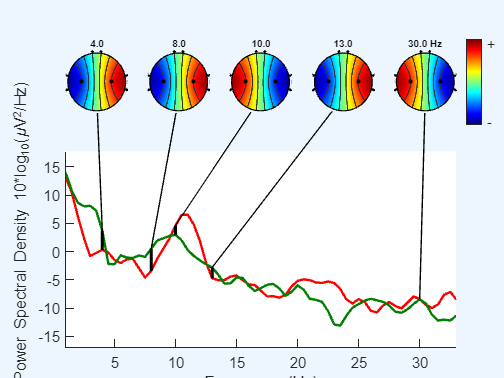


base_tlen = [idx_base-1 idx_base];
cond_plot_spectra(EEG, {'1000'}, base_tlen, freqs_array, {{'C3', 'C4'}},freqfac, "", [], 'on');


EEG_cond_epoch = pop_epoch(EEG, {'1000'}, base_tlen);

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});

Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


**Time window which has the highest correlation (averaged across 3 bands) with the spectra (PSD) averaged across all baseline (8sec) epochs - will be used for further analysis**

## Check correlation: comparing power spectrum of 1-sec window with that of full-length baseline epochs (C3) (Using the AOE epochs

% base_tlen = [0 8];
% [spectra_base, ~, ~] = cond_plot_spectra(EEG, num2cell(markerVal_AE_num), base_tlen, ...
%         freqs_array, {{'C3'}}, freqfac, "", [], 'off');
% 
% 
% corrcoef_cell = [];
% for t = base_tlen(1):base_tlen(2)
%     tlen = t-1:t;
%     EEG_cond_epoch = cond_epoch(EEG, {'1000'}, tlen);
%     EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
%     [spectra,freqs,~,~,~] = pop_spectopo(EEG_cond_chan, 1, [tlen(1) tlen(end)]*1000, 'EEG',...
%         'freq', freqs_array, 'plot', 'off', 'verbose', 'off', 'freqfac', freqfac);
%     R = 0;
%     for f = 1:3
%             spectra_band = spectra(1, freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end));
%             spectra_base_band = spectra_base( freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end));
%             R_band = corrcoef(spectra_band, spectra_base_band);
%             R = R + R_band(1,2);
%     end
%     R = R/3;
%     corrcoef_cell = [corrcoef_cell R];
% end
% corrcoef_cell
% [~, idx_base] = max(corrcoef_cell)
% 
% base_tlen = [idx_base-1 idx_base];
% cond_plot_spectra(EEG, {'1000'}, base_tlen, freqs_array, {{'C3', 'C4'}},freqfac, "", [], 'on');


## Stim epochs

### Plot power spectrum density of conditions

% stim_epoch = [0 4];
% figure(); 
% for i = 1:4
%     events_cell = num2cell(markerVal_num((i-1)*8+1:i*8));
%     tlen = stim_epoch;
%     plottitle = [];
%     EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);
% 
% 
%     EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3', 'C4'});
%     subplot(2,2,i); title(plottitle);
%     [spectra,freqs,speccomp,contrib,specstd] = pop_spectopo(EEG_cond_chan, 1, tlen*1000, 'EEG',...
%         'freq', freqs_array, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', 'on', 'verbose', 'off');
% end


### Compute Spectrogram of the stim epoch: time-frequency transform (using newtimef with option 'Baseline' being NaN) (C3)

Angelini 2018

base_tlen = [idx_base-1 idx_base];
[spectra_base, freqs_base, specstd_base] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3'}}, freqfac, "", [], 'off');

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


spectra_base = spectra_base(freqs_base >= 4 & freqs_base <= 30);
% spectra_base_abs = 10.^(spectra_base./10);

figure(); title('Power Spectrum (10*log_{10}(\muV^{2}/Hz)');
hold on
plot(4:0.5:30, spectra_base + 10*log10(128/2),'DisplayName', 'baseline (1sec epoch)')

stim_tlen = [-0.5 4];
for i=1:4
    [spectra_stim, freqs_stim, ~] = cond_plot_spectra(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
            freqs_array, {{'C3'}}, freqfac, "", [], 'off');
    spectra_stim = spectra_stim(freqs_stim >= 4 & freqs_stim <= 30);
    spectra_stim_abs = 10.^(spectra_stim./10);
    
    plot(4:0.5:30, spectra_stim+ 10*log10(128/2),'DisplayName', markerLabel(i))
end

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'key', 'val' par

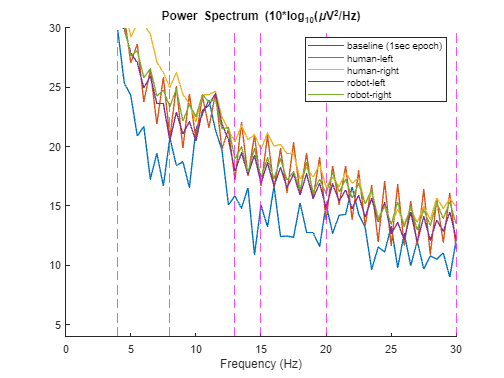

xlabel('Frequency (Hz)')
xline([4 8 13 15 20 30], '--', 'Color', 'magenta', 'HandleVisibility','off')
ylim([4 30])
hold off; legend({})

### Compute ERD/S

Grandchamp and Delorme 2011

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


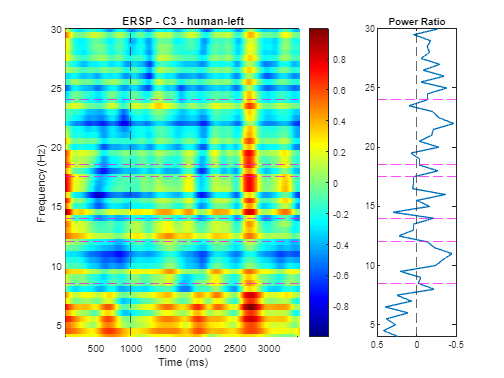

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


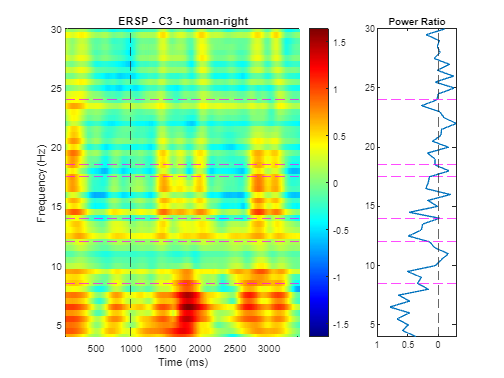

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


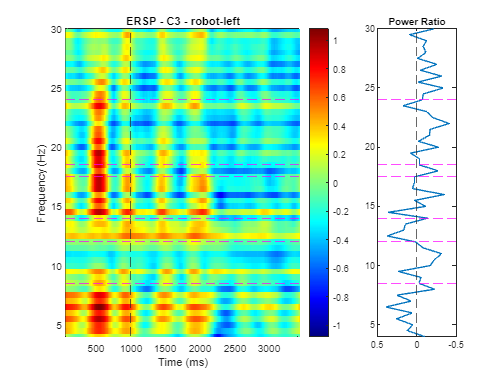

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


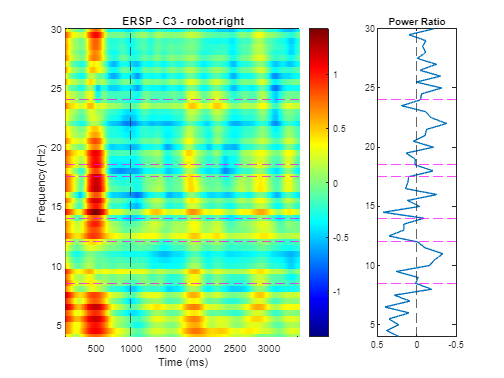

% stim_tlen = [-1 4];
ersp_mean_C3 = cell(1,4);
ersp_C3 = cell(1,4);

for i=1:4
    EEG_cond_epoch = pop_epoch(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen);
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
    % figure(); title('stim')
    [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
        pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 15.36], ...
        'freqs', [4 30],'nfreqs', length(4:0.5:30), 'plotitc', 'off', 'plotersp', 'off', ...
        'verbose', 'off', 'baseline', NaN, 'timesout', timesout_stim);
    
    % Baseline correction
    ersp_baseln = zeros(size(ersp));
    for row = 1:height(ersp)
        ersp_baseln(row, :) = ersp(row, :) - (spectra_base(row) + 10*log10(128/2));
    end
    % ersp_baseln = 10.^(ersp_baseln/10); %convert from 10log10 to absolute
    ersp_baseln = ersp_baseln/10; %convert to log10 scale
    ersp_baseln_mean = mean(ersp_baseln, 2);

    ersp_C3{i} = ersp_baseln;
    ersp_mean_C3{i} = ersp_baseln_mean;

    figure();
    subplot(1,4,1:3); hold on
    % imagesc(times, freqs, 10.^(ersp_baseln/10)); box on
    imagesc(times, freqs, ersp_baseln); box on
    xline([0 1000], '--');
    yline([8.5 12 14 17.5 18.5 24], '--', 'Color', 'magenta')
    max_val = max(abs(ersp_baseln(:))); clim([-max_val max_val])
    axis xy; colormap(jet(256)); colorbar; xlabel('Time (ms)'); ylabel('Frequency (Hz)');
    ylim([4 30]); xlim([min(times) max(times)]);
    title('ERSP - C3 - '+ markerLabel(i))
    hold off
    subplot(1,4,4); hold on; title('Power Ratio')
    plot(ersp_baseln_mean, freqs)
    yline([8.5 12 14 17.5 18.5 24], '--', 'Color', 'magenta'); xline(0, '--')
    ylim([4 30])%; xlim([0 2]); xticks(0:0.5:2)
    set ( gca, 'xdir', 'reverse' ); box on
    hold off
end

times_stim = times;

We can see peaks around these ranges: 8.5-12 Hz (mu band), 14-17.5 Hz and 18.5-24 Hz.

Beta rhythms (13–30 Hz) are present throughout the motor system in the absence of movement.

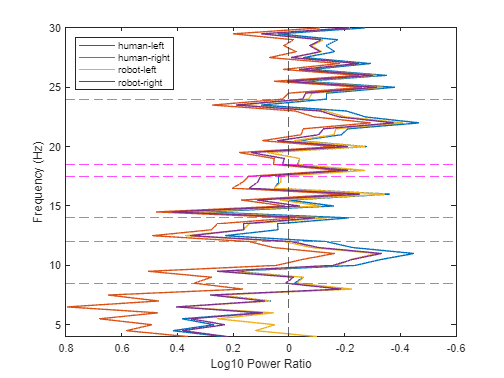

figure(); hold on;% title('Power Ratio')
for i=1:4
    plot(ersp_mean_C3{i}, freqs, 'DisplayName', markerLabel(i))
end
yline([8.5 12 14 17.5 18.5 24], '--', 'Color', 'magenta', 'HandleVisibility','off'); 
xline(0, '--', 'HandleVisibility','off')
ylim([4 30]); ylabel('Frequency (Hz)'); xlabel('Log10 Power Ratio');
set ( gca, 'xdir', 'reverse' ); box on
legend('Location','northwest');
hold off

#### Compute ERD/S for each action types (and for each action)

% base_tlen = [idx_base-1 idx_base];
% [spectra_base, freqs_base, ~] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
%         freqs_array, {{'C3'}}, freqfac, "", [], 'off');
% spectra_base = spectra_base(freqs_base >= 4 & freqs_base <= 30);
% % spectra_base_abs = 10.^(spectra_base./10);
% 
% stim_tlen = [-0.5 4];
% 
% for i=1:4
%     for at = 1:2
%         EEG_cond_epoch = pop_epoch(EEG, num2cell(i*10 + actions{at}), stim_tlen);
%         EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
%         % figure(); title('stim')
%         [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
%             pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 15.36], ...
%             'freqs', [4 30],'nfreqs', length(4:0.5:30), 'plotitc', 'off', 'plotersp', 'off', ...
%             'verbose', 'off', 'baseline', NaN, 'timesout', timesout_stim);
% 
%         % Baseline correction
%         ersp_baseln = zeros(size(ersp));
%         for row = 1:height(ersp)
%             ersp_baseln(row, :) = ersp(row, :) - (spectra_base(row) + 10*log10(128/2));
%         end
%         % ersp_baseln = 10.^(ersp_baseln/10); %convert from 10log10 to absolute
%         ersp_baseln = ersp_baseln/10; %convert to log10 scale
%         ersp_baseln_mean = mean(ersp_baseln, 2);
% 
%         % ersp_C3{i} = ersp_baseln;
%         % ersp_mean_C3{i} = ersp_baseln_mean;
% 
%         figure();
%         subplot(1,4,1:3); hold on
%         % imagesc(times, freqs, 10.^(ersp_baseln/10)); box on
%         imagesc(times, freqs, ersp_baseln); box on
%         xline([0 1000], '--');
%         yline([8.5 12 14 17.5 18.5 24], '--', 'Color', 'magenta')
%         max_val = max(abs(ersp_baseln(:))); clim([-max_val max_val])
%         axis xy; colormap(jet(256)); colorbar; 
%         xlabel('Time (ms)'); ylabel('Frequency (Hz)');
%         ylim([4 30]); xlim([min(times) max(times)]);
%         title('ERSP - C3 - '+ markerLabel(i)+ ' - '+ actions_type_names{at})
%         hold off
%         subplot(1,4,4); hold on; title('Power Ratio')
%         plot(ersp_baseln_mean, freqs)
%         yline([8.5 12 14 17.5 18.5 24], '--', 'Color', 'magenta'); xline(0, '--')
%         ylim([4 30])%; xlim([0 2]); xticks(0:0.5:2)
%         set ( gca, 'xdir', 'reverse' ); box on
%         hold off
%     end
% 
% end


### Compute ERDS for channel C4

Run the same steps: find the baseline time window with highest correlation of power spectrum with the full-length baseline epochs; compute power spectrum and spectrogram of stim epochs; compute ERD/S

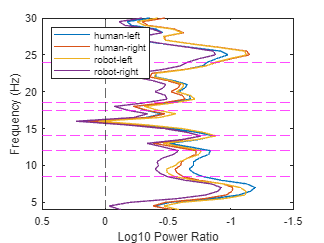

base_tlen = [1 6];

[spectra_base, ~, ~] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C4'}}, freqfac, "", [], 'off');


corrcoef_cell = [];
for t = base_tlen(1):base_tlen(2)

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 1000.00 ms to 6000.00 ms (points 1 to 640)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


    tlen = t-1:t;
    EEG_cond_epoch = cond_epoch(EEG, {'1000'}, tlen);
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C4'});
    [spectra,freqs,~,~,~] = pop_spectopo(EEG_cond_chan, 1, [tlen(1) tlen(end)]*1000, 'EEG',...
        'freq', freqs_array, 'plot', 'off', 'verbose', 'off', 'freqfac', freqfac);
    R = 0;
        for f = 1:length(freq_bands_bl)
            spectra_band = spectra(1, freqs >= freq_bands_bl{f}(1) & freqs <= freq_bands_bl{f}(end));
            spectra_base_band = spectra_base( freqs >= freq_bands_bl{f}(1) & freqs <= freq_bands_bl{f}(end));
            R_band = corrcoef(spectra_band, spectra_base_band);
            R = R + R_band(1,2);
        end
    R = R/length(freq_bands_bl);
    corrcoef_cell = [corrcoef_cell R];
end
corrcoef_cell
[~, idx_base] = max(corrcoef_cell)

base_tlen = [idx_base-1 idx_base];

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


cond_plot_spectra(EEG, {'1000'}, base_tlen, freqs_array, {{'C3', 'C4'}},freqfac, "", [], 'on');

corrcoef_cell =     0.6044    0.3551    0.5070    0.6631    0.4738    0.6850


%---------------------------------------------------------------

idx_base = 6

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 30 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
..
Plotting scalp distributions: .....
Click on each trace for channel/component index


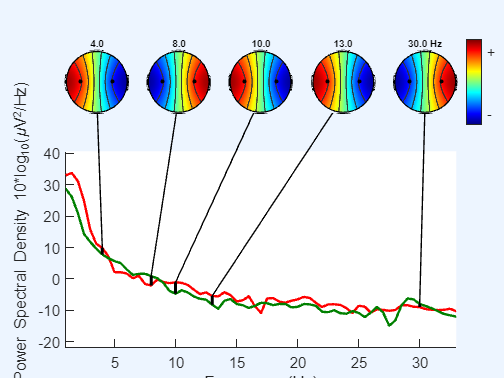

base_tlen = [idx_base-1 idx_base];
[spectra_base, freqs_base, specstd_base] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C4'}}, freqfac, "", [], 'off');

spectra_base = spectra_base(freqs_base >= 4 & freqs_base <= 30);
spectra_base_abs = 10.^(spectra_base./10);

f1 = figure;

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.



figure(f1); title('Power Spectrum (10*log_{10}(\muV^{2}/Hz)');
hold on
plot(4:0.5:30, spectra_base + 10*log10(128/2),'DisplayName', 'baseline')

stim_tlen = [-0.5 4];
for i=1:4
    [spectra_stim, freqs_stim, ~] = cond_plot_spectra(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
            freqs_array, {{'C4'}}, freqfac, "", [], 'off');
    spectra_stim = spectra_stim(freqs_stim >= 4 & freqs_stim <= 30);
    spectra_stim_abs = 10.^(spectra_stim./10);
    
    plot(4:0.5:30, spectra_stim+ 10*log10(128/2),'DisplayName', markerLabel(i))
end
xlabel('Frequency (Hz)')
xline([4 8 13 15 20 30], '--', 'Color', 'magenta', 'HandleVisibility','off')
ylim([4 30])
legend(); hold off; 

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 m

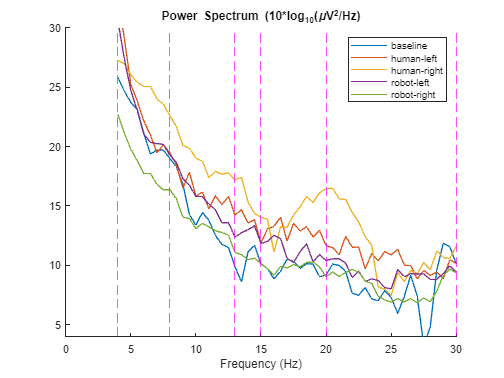


ersp_mean_C4 = cell(1,4);
ersp_C4 = cell(1,4);


% stim_tlen = [0 4];
for i=1:4
    EEG_cond_epoch = pop_epoch(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen);
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C4'});
    % figure(); title('stim')
    [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
        pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 15.36], ...
        'freqs', [4 30],'nfreqs', length(4:0.5:30), 'plotitc', 'off', 'plotersp', 'off', ...
        'verbose', 'off', 'baseline', NaN, 'timesout', timesout_stim);
    
    % Baseline correction
    ersp_baseln = zeros(size(ersp));
    for row = 1:height(ersp)
        ersp_baseln(row, :) = ersp(row, :) - (spectra_base(row) + 10*log10(128/2));
    end
    % ersp_baseln = 10.^(ersp_baseln/10); %convert from 10log10 to absolute
    ersp_baseln = ersp_baseln/10; %convert to log10 scale
    ersp_baseln_mean = mean(ersp_baseln, 2);

    ersp_C4{i} = ersp_baseln;
    ersp_mean_C4{i} = ersp_baseln_mean;

    figure();
    subplot(1,4,1:3); hold on
    imagesc(times, freqs, ersp_baseln); box on
    xline([0 1000], '--');
    yline([4 8 13 15 20 30], '--', 'Color', 'magenta')
    max_val = max(abs(ersp_baseln(:))); clim([-max_val max_val])
    axis xy; colormap(jet(256)); colorbar; xlabel('Time (ms)'); ylabel('Frequency (Hz)');
    ylim([4 30]); xlim([min(times) max(times)]);
    title('ERSP - C4', markerLabel(i))
    hold off
    subplot(1,4,4); hold on; title('Power Ratio')
    plot(ersp_baseln_mean, freqs)
    yline([4 8 13 15 20 30], '--', 'Color', 'magenta'); xline(0, '--')
    ylim([4 30])%; xlim([0 2]); xticks(0:0.5:2)
    set ( gca, 'xdir', 'reverse' ); box on
    hold off
end

## Data analysis (C3)

Boni et al 2023

independent sample t-tests to comapre power suppression between ACTOR, SIDE factors

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


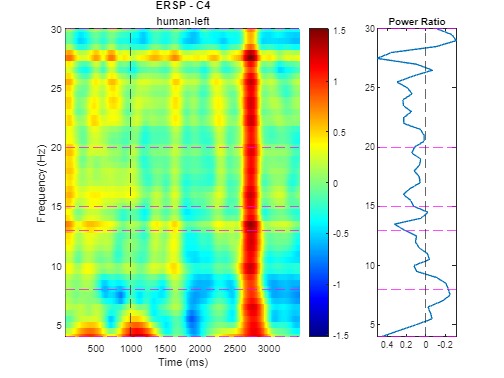

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


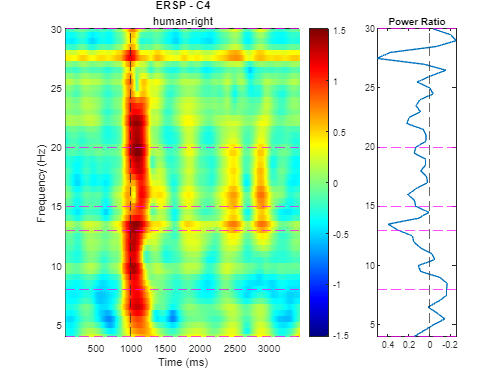

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


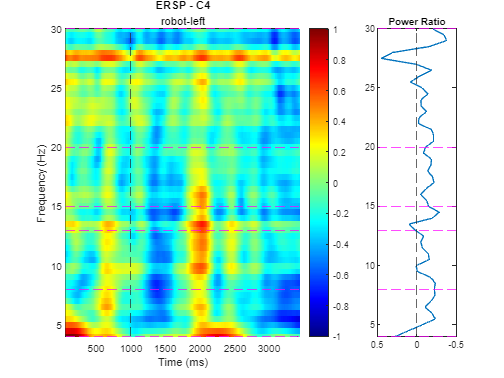

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


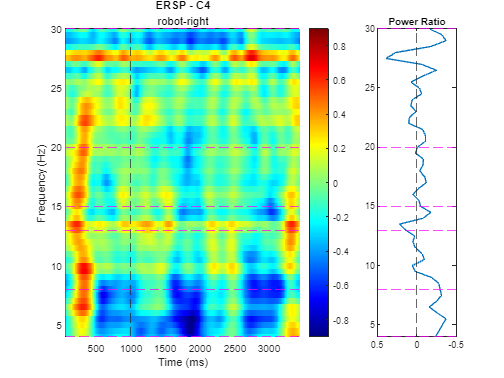

% freqs = 4:0.5:30;
% ersp_C3_bands = cell(1,4);
% 
% freq_bands_sig =  {[8.5 12], [14 17.5], [18.5 24]};

% band_names_sig = ["alpha" "beta (14-17.5Hz)" "beta (18.5-24Hz)"];
% for i = 1:4
%     ersp_array = ersp_C3{i} ;
%     ersp_bands = [];
%     for f = 1:3
%         ersp_bands = [ersp_bands; mean(ersp_array(freqs >= freq_bands_sig{f}(1) & freqs <= freq_bands_sig{f}(end), :) )];
%     end
%     ersp_C3_bands{i} = ersp_bands;
% end
% 
% 
% for fp = 1:2
%     actor_pair_names{fp}
%     for f = 1:3
%         band_names_sig(f)
%         ersp_data1 = ersp_C3_bands{actor_pair{fp}(1)};
%         ersp_data2 = ersp_C3_bands{actor_pair{fp}(2)};
%         [h, p] = ttest2(ersp_data1(f, :), ersp_data2(f, :), 'Tail', 'right')
%     end
% end
% 
% for fp = 1:2
%     side_pair_names{fp}
%     for f = 1:3
%         band_names_sig(f)
%         ersp_data1 = ersp_C3_bands{side_pair{fp}(1)};
%         ersp_data2 = ersp_C3_bands{side_pair{fp}(2)};
%         [h, p] = ttest2(ersp_data1(f, :), ersp_data2(f, :), 'Tail', 'right')
%     end
% end

Hypothesis test result, returned as `1` or `0`.

- If `h` `= 1`, this indicates the rejection of the null hypothesis at the [`Alpha`](https://www.mathworks.com/help/stats/ttest2.html#btqjrsu_sep_shared-Alpha) significance level.

- If `h` `= 0`, this indicates a failure to reject the null hypothesis at the `Alpha` significance level.

Results are messy. 

### Angelini 2018

#### Step 1: Confirm if ERDs are significant by comparing log10 power ratio with 0 using one-tail one-sample t-test

Single-subject values were averaged across Observed Hand (LH, RH) and central left and right clusters of electrodes, separately for each perspective and frequency band. Log10 AO ratio data were tested in one-tailed single-sample t tests against 0 (p < 0.05). For each perspective, log10 ratio values significantly lower than 0 indicated significant suppression of central alpha and beta components during AO relative to the baseline.

freqs = 4:0.5:30;
ersp_C3_bands = cell(1,4);

freq_bands_sig =  {[8.5 12], [14 17.5], [18.5 24]};
band_names_sig = ["alpha" "beta (14-17.5Hz)" "beta (18.5-24Hz)"];

Choosing these frequency bands based on observations of ERD at C3. This might be a limitation.


for i = 1:4
    ersp_array = ersp_C3{i} ;
    ersp_bands = [];
    for f = 1:3
        ersp_bands = [ersp_bands; mean(ersp_array(freqs >= freq_bands_sig{f}(1) & freqs <= freq_bands_sig{f}(end), :) )];
    end
    ersp_C3_bands{i} = ersp_bands;
end

"C3" + newline + "One tailed single sample t test" + newline + "Actor"

ans =     "C3
     One tailed single sample t test
     Actor"


for fp = 1:2
    actor_pair_names{fp}
    for f = 1:3
        band_names_sig(f)
        ersp_cond1 = ersp_C3_bands{actor_pair{fp}(1)};
        ersp_cond2 = ersp_C3_bands{actor_pair{fp}(2)};
        [h, p, ~, stats] = ttest((ersp_cond1(f, :)+ ersp_cond2(f,:))/2, zeros(size(ersp_cond1(f, :))), 'Tail', 'left')
    end
end

ans = 1×2 string array
    "human-left"    "human-right"


ans = "alpha"

h = 0

p = 1

stats = struct with fields:
    tstat: 28.6746
       df: 399
       sd: 0.1149


ans = "beta (14-17.5Hz)"

h = 0

p = 1

stats = struct with fields:
    tstat: 41.0484
       df: 399
       sd: 0.1495


ans = "beta (18.5-24Hz)"

h = 0

p = 1

stats = struct with fields:
    tstat: 21.0792
       df: 399
       sd: 0.1290


ans = 1×2 string array
    "robot-left"    "robot-right"


ans = "alpha"

h = 0

p = 1

stats = struct with fields:
    tstat: 26.2457
       df: 399
       sd: 0.1870


ans = "beta (14-17.5Hz)"

h = 0

p = 1

stats = struct with fields:
    tstat: 15.7686
       df: 399
       sd: 0.2552


ans = "beta (18.5-24Hz)"

h = 0

p = 1

stats = struct with fields:
    tstat: 11.8361
       df: 399
       sd: 0.2126



newline + "Observed Hand"

ans =     "
     Observed Hand"


for fp = 1:2
    side_pair_names{fp}
    for f = 1:3
        band_names_sig(f)
        ersp_cond1 = ersp_C3_bands{side_pair{fp}(1)};
        ersp_cond2 = ersp_C3_bands{side_pair{fp}(2)};
        [h, p, ~, stats] = ttest((ersp_cond1(f, :)+ ersp_cond2(f,:))/2, zeros(size(ersp_cond1(f, :))), 'Tail', 'left')
    end
end

ans = 1×2 string array
    "human-left"    "robot-left"


ans = "alpha"

h = 0

p = 1

stats = struct with fields:
    tstat: 25.9352
       df: 399
       sd: 0.1180


ans = "beta (14-17.5Hz)"

h = 0

p = 1

stats = struct with fields:
    tstat: 17.6465
       df: 399
       sd: 0.2056


ans = "beta (18.5-24Hz)"

h = 0

p = 1.0000

stats = struct with fields:
    tstat: 6.6038
       df: 399
       sd: 0.1737


ans = 1×2 string array
    "human-right"    "robot-right"


ans = "alpha"

h = 0

p = 1

stats = struct with fields:
    tstat: 30.0376
       df: 399
       sd: 0.1712


ans = "beta (14-17.5Hz)"

h = 0

p = 1

stats = struct with fields:
    tstat: 33.7517
       df: 399
       sd: 0.1936


ans = "beta (18.5-24Hz)"

h = 0

p = 1

stats = struct with fields:
    tstat: 24.2289
       df: 399
       sd: 0.1688


All one-sample t-test show significant ERD at the frequency bands of interest.

#### step 1 - C4 channel

freqs = 4:0.5:30;
ersp_C4_bands = cell(1,4);

freq_bands_sig =  {[8.5 12], [14 17.5], [18.5 24]};
band_names_sig = ["alpha" "beta (14-17.5Hz)" "beta (18.5-24Hz)"];

for i = 1:4
    ersp_array = ersp_C4{i} ;
    ersp_bands = [];
    for f = 1:3
        ersp_bands = [ersp_bands; mean(ersp_array(freqs >= freq_bands_sig{f}(1) & freqs <= freq_bands_sig{f}(end), :) )];
    end
    ersp_C4_bands{i} = ersp_bands;
end

"C4" + newline + "One tailed single sample t test" + newline + "Actor"

ans =     "C4
     One tailed single sample t test
     Actor"


for fp = 1:2
    actor_pair_names{fp}
    for f = 1:3
        band_names_sig(f)
        ersp_cond1 = ersp_C4_bands{actor_pair{fp}(1)};
        ersp_cond2 = ersp_C4_bands{actor_pair{fp}(2)};
        % compute the mean of log10 power ratio data between conditions
        % (eg. human-right and human-left)
        [h, p, ~, stats] = ttest((ersp_cond1(f, :)+ ersp_cond2(f,:))/2, zeros(size(ersp_cond1(f, :))), 'Tail', 'left')
    end
end

ans = 1×2 string array
    "human-left"    "human-right"


ans = "alpha"

h = 0

p = 0.7210

stats = struct with fields:
    tstat: 0.5863
       df: 399
       sd: 0.2305


ans = "beta (14-17.5Hz)"

h = 0

p = 1

stats = struct with fields:
    tstat: 9.7412
       df: 399
       sd: 0.2048


ans = "beta (18.5-24Hz)"

h = 0

p = 1

stats = struct with fields:
    tstat: 11.1471
       df: 399
       sd: 0.2057


ans = 1×2 string array
    "robot-left"    "robot-right"


ans = "alpha"

h = 1

p = 2.8229e-31

stats = struct with fields:
    tstat: -12.6247
       df: 399
       sd: 0.1323


ans = "beta (14-17.5Hz)"

h = 1

p = 4.7126e-62

stats = struct with fields:
    tstat: -19.9108
       df: 399
       sd: 0.1177


ans = "beta (18.5-24Hz)"

h = 1

p = 1.0796e-37

stats = struct with fields:
    tstat: -14.2151
       df: 399
       sd: 0.0927



newline + "Observed Hand"

ans =     "
     Observed Hand"


for fp = 1:2
    side_pair_names{fp}
    for f = 1:3
        band_names_sig(f)
        ersp_cond1 = ersp_C4_bands{side_pair{fp}(1)};
        ersp_cond2 = ersp_C4_bands{side_pair{fp}(2)};
        [h, p, ~, stats] = ttest((ersp_cond1(f, :)+ ersp_cond2(f,:))/2, zeros(size(ersp_cond1(f, :))), 'Tail', 'left')
    end
end

ans = 1×2 string array
    "human-left"    "robot-left"


ans = "alpha"

h = 1

p = 5.1712e-08

stats = struct with fields:
    tstat: -5.4199
       df: 399
       sd: 0.1902


ans = "beta (14-17.5Hz)"

h = 1

p = 1.0629e-04

stats = struct with fields:
    tstat: -3.7380
       df: 399
       sd: 0.1721


ans = "beta (18.5-24Hz)"

h = 0

p = 0.6729

stats = struct with fields:
    tstat: 0.4484
       df: 399
       sd: 0.1559


ans = 1×2 string array
    "human-right"    "robot-right"


ans = "alpha"

h = 1

p = 0.0039

stats = struct with fields:
    tstat: -2.6700
       df: 399
       sd: 0.1887


ans = "beta (14-17.5Hz)"

h = 0

p = 0.9442

stats = struct with fields:
    tstat: 1.5950
       df: 399
       sd: 0.1853


ans = "beta (18.5-24Hz)"

h = 0

p = 1.0000

stats = struct with fields:
    tstat: 4.8329
       df: 399
       sd: 0.1874


Significant ERD seen at 2 beta sub-bands (not all tests), but not at alpha/mu band

### Step 2: Analyse each time windows within stim epochs => find the significant time windows

We need to separate 2 types of action:

1) actions with 1-sec stll hand

2) actions with first-sec pre action

% times_array = times_stim;
%
% % separate stim epochs into time windows
% tWin_idx = {times_array <= 1000, times_array >= 1000 & times_array <= 1500, times_array >= 1500 & times_array <= 2000, times_array >= 2000 & times_array <= 2500, times_array >= 2500 & times_array <= 3000, times_array >= 3000 & times_array <= 3500 };
%
% for fp = 1:2
%     for f = 1:3
%         ersp_cond1 = ersp_C3_bands{actor_pair{fp}(1)};
%         ersp_cond2 = ersp_C3_bands{actor_pair{fp}(2)};
%         ersp_mean_cond = (ersp_cond1(f, :)+ ersp_cond2(f,:))/2;
%         for tw = 1:length(tWin_idx)
%

Update 2/1/2024: This might get very complicated. Considering skipping this and using the whole main AO time window (from 1000ms to 4000ms of time epoch) for further analysis.

Update: repeated measures ANOVA can be used for single subject measured under different condiitons or multiple times

step 2:

% times_array = times_stim;
% 
% % separate stim epochs into time windows
% tWin_idx = {times_array <= 1000, times_array >= 1000 & times_array <= 1500, times_array >= 1500 & times_array <= 2000, times_array >= 2000 & times_array <= 2500, times_array >= 2500 & times_array <= 3000, times_array >= 3000 & times_array <= 3500 };
% 
% for fp = 1:2
%     for f = 1:3
%         ersp_cond1 = ersp_C3_bands{actor_pair{fp}(1)};
%         ersp_cond2 = ersp_C3_bands{actor_pair{fp}(2)};
%         ersp_mean_cond = (ersp_cond1(f, :)+ ersp_cond2(f,:))/2;
%         for tw = 1:length(tWin_idx)
%         end
%     end
% end


function [ersp_out, times, freqs_out, erspboot_out ] = cond_ersp(EEG, events_cell, tlen, sub_epoch_len, freqs, channels, erspmax, alpha, plottitle, filepath, toPlot)
    EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);
    if length(channels) == 1
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', channels);
        if alpha ~= 0
            if string(toPlot) == "off"
                [ersp_out,~,~,times,freqs_out,erspboot_out,~,~] = ...
                pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            else
                figure;
            [ersp_out,~,~,times,freqs_out,erspboot_out,~,~] = ...
                pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            end
            else
            figure; 
            [ersp_out,~,~,times,freqs_out,erspboot_out,~,~] = ...
                pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot,'erspmax', erspmax, 'verbose', 'off');
        end
    
    elseif length(channels) == 2
        EEG_cond_chan1 = pop_select( EEG_cond_epoch, 'channel', channels(1));
        EEG_cond_chan2 = pop_select( EEG_cond_epoch, 'channel', channels(2));

        if alpha ~= 0
            if string(toPlot) == "off"
                [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
                [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            else

            figure; sgtitle(plottitle)
            subplot(2,1,1); 
            [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            title(string(channels(1)))
            subplot(2,1,2); 
            [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            title(string(channels(2)))
            end
        else 
            if string(toPlot) == "off"
                [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
                [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
            else

            figure; sgtitle(plottitle)
            subplot(2,1,1); 
            [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
            title(string(channels(1)))
            subplot(2,1,2); 
            [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
            title(string(channels(2)))
            end
        end
        save_figures(filepath, plottitle, toPlot)
        ersp_out = {ersp1, ersp2}; erspboot_out = {erspboot1, erspboot2};
    end

end
%=================================================================
% function 

% ===================================================
function [spectra,freqs,specstd] = cond_plot_spectra(EEG, events_cell, tlen, freqs, chanlocs, freqfac, plottitle, filepath, toPlot)
    EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);
    
    if length(chanlocs) == 1
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', chanlocs{1});
        if string(toPlot) == "on"
            figure; title(plottitle);
        end
        [spectra,freqs,speccomp,contrib,specstd] = pop_spectopo(EEG_cond_chan, 1, tlen*1000, 'EEG', 'freqfac', freqfac,...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');

    elseif length(chanlocs) == 2
        EEG_cond_RH = pop_select( EEG_cond_epoch, 'channel',chanlocs{1});
        EEG_cond_LH = pop_select( EEG_cond_epoch, 'channel',chanlocs{1}); 
        figure; sgtitle(plottitle);
        subplot(211); 
        pop_spectopo(EEG_cond_RH, 1, tlen*1000, 'EEG', 'freqfac', freqfac,...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');
        subplot(212); 
        pop_spectopo(EEG_cond_LH, 1, tlen*1000, 'EEG', 'freqfac', freqfac,...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');
    end
    % save_figures(filepath, plottitle, toPlot)
end


%===================================================
function OUTEEG = cond_epoch(EEG, events_cell, tlen)
    % events_cell
    EEG_epoch = pop_epoch(EEG, events_cell, tlen, 'verbose', 'off');
    OUTEEG = pop_rmbase(EEG_epoch, [0 0.5]*1000);

end


function save_figures(filepath, plottitle, toPlot)
    if string(toPlot) == "on"
        savefig(fullfile(filepath, plottitle+".fig"));
        saveas(gcf, fullfile(filepath, plottitle+".png")) 
    end
end


%=================================================================
function plot_ersp_band(times, mean_ersp_bands, std_ersp_bands, cond_num, band_colors, band_names, chan_name)
    hold on;
    xline(0, 'k--','Alpha', 0.5, 'HandleVisibility', 'off')
    yline(0, 'k--','Alpha', 0.5, 'HandleVisibility', 'off')
    for i = 1:length(mean_ersp_bands)
        plot(times, mean_ersp_bands{1,i}, 'Color', band_colors(i), 'DisplayName', band_names(i))
        fill([times, fliplr(times)], [mean_ersp_bands{1,i} + std_ersp_bands{1,i}, ...
            fliplr(mean_ersp_bands{1,i} - std_ersp_bands{1,i})], band_colors(i), 'EdgeColor', 'none', ...
            'FaceAlpha', 0.2, 'HandleVisibility', 'off');
    end
    if cond_num == 1
        title(chan_name); 
    end
    xlim([min(times), max(times)]);
    ylabel('ERDS (dB)'); xlabel('time [ms]')
    hold off;
end













